## Declare variables and vectors

clear
syms L v
assume(L,'positive')
assume(v,'real')
syms x y theta
assume(x,'real')
assume(y,'real')
assume(theta,'real')
syms delta
assume(delta,'real')


dims = [L]'

$$dims = L$$

X = [x y theta]'

$$X = \left(\begin{array}{c} x\\ y\\ \theta \end{array}\right)$$

U = [delta v]'

$$U = \left(\begin{array}{c} \delta \\ v \end{array}\right)$$

## Create dX

x_dot = v*cos(theta)

$$x\_dot = v\,\cos\left(\theta \right)$$

y_dot = v*sin(theta)

$$y\_dot = v\,\sin\left(\theta \right)$$

theta_t_dot = v * tan(delta)/ L;

dX = [
    x_dot
    y_dot
    theta_t_dot
]

$$dX = \left(\begin{array}{c} v\,\cos\left(\theta \right)\\ v\,\sin\left(\theta \right)\\ \frac{v\,\tan\left(\delta \right)}{L} \end{array}\right)$$

## Find Jacobians

A = jacobian(dX,X)

$$A = \left(\begin{array}{ccc} 0 & 0 & -v\,\sin\left(\theta \right)\\ 0 & 0 & v\,\cos\left(\theta \right)\\ 0 & 0 & 0 \end{array}\right)$$

B = jacobian(dX,U)

$$B = \left(\begin{array}{cc} 0 & \cos\left(\theta \right)\\ 0 & \sin\left(\theta \right)\\ \frac{v\,\left({\tan\left(\delta \right)}^{2}+1\right)}{L} & \frac{\tan\left(\delta \right)}{L} \end{array}\right)$$

## Simplify with small angle approximations

% As = applySmallAngleApproximations(A)
% Bs = applySmallAngleApproximations(B)

A = simplify(A,'IgnoreAnalyticConstraints',true)

$$A = \left(\begin{array}{ccc} 0 & 0 & -v\,\sin\left(\theta \right)\\ 0 & 0 & v\,\cos\left(\theta \right)\\ 0 & 0 & 0 \end{array}\right)$$

B = simplify(B,'IgnoreAnalyticConstraints',true)

$$B = \left(\begin{array}{cc} 0 & \cos\left(\theta \right)\\ 0 & \sin\left(\theta \right)\\ \frac{v\,\left({\tan\left(\delta \right)}^{2}+1\right)}{L} & \frac{\tan\left(\delta \right)}{L} \end{array}\right)$$

% As = simplify(As,'IgnoreAnalyticConstraints',true)
% Bs = simplify(Bs,'IgnoreAnalyticConstraints',true)

## Review matricies

A

$$A = \left(\begin{array}{ccc} 0 & 0 & -v\,\sin\left(\theta \right)\\ 0 & 0 & v\,\cos\left(\theta \right)\\ 0 & 0 & 0 \end{array}\right)$$

B

$$B = \left(\begin{array}{cc} 0 & \cos\left(\theta \right)\\ 0 & \sin\left(\theta \right)\\ \frac{v\,\left({\tan\left(\delta \right)}^{2}+1\right)}{L} & \frac{\tan\left(\delta \right)}{L} \end{array}\right)$$

dX_rejoin = A*X+B*U

$$dX\_rejoin = \left(\begin{array}{c} v\,\cos\left(\theta \right)-\theta \,v\,\sin\left(\theta \right)\\ v\,\sin\left(\theta \right)+\theta \,v\,\cos\left(\theta \right)\\ \frac{v\,\tan\left(\delta \right)}{L}+\frac{\delta \,v\,\left({\tan\left(\delta \right)}^{2}+1\right)}{L} \end{array}\right)$$

% As
% Bs
% dXs_rejoin = As*X+Bs*U

## Output function file

% matlabFunction(A,B,'File','getAB','Vars',{dims,X,U})

## Compare dX vs dX_rejoin

v = -1;
L = 2;

thetas = linspace(-pi, pi, 100);
deltas = linspace(-pi/4,pi/4,100);

dx1 = zeros(100,1);
dy1 = zeros(100,1);
dtheta1 = zeros(100,1);
dx2 = zeros(100,1);
dy2 = zeros(100,1);
dtheta2 = zeros(100,1);
dx3 = zeros(100,1);
dy3 = zeros(100,1);
dtheta3 = zeros(100,1);

theta0 =deg2rad(0);
delta0 =deg2rad(0);

for i = 1:100
    theta = thetas(i);
    delta = deltas(i);

    dx1(i) = v*cos(theta);
    dy1(i) = v*sin(theta);
    dtheta1(i) = v*tan(delta)/L;
        
    dx2(i) = v*cos(theta0) - v*sin(theta0)*(theta-theta0);
    dy2(i) = v*sin(theta0) + v*cos(theta0)*(theta-theta0);
    dtheta2(i) = v*tan(delta0)/L + v*(tan(delta0)^2 + 1)/L*(delta-delta0);
    
    dx3(i) = v*cos(theta0) - v*sin(theta0)*(theta-theta0);
    dy3(i) = v*sin(theta0) + v*cos(theta0)*(theta-theta0);
    dtheta3(i) = v*tan(delta0)/L + v*(tan(delta0)^2 + 1)/L*(delta-delta0);
end

figure(1), clf
subplot(1,3,1), hold on
plot(rad2deg(thetas),dx1)
plot(rad2deg(thetas),dx2)
% plot(rad2deg(thetas),dx3,'k')
title("dx vs \theta")
xlabel("\theta")
ylabel("dx")
legend("Norm","AB","AB linearised")


subplot(1,3,2), hold on
plot(rad2deg(thetas),dy1)
plot(rad2deg(thetas),dy2)
% plot(rad2deg(thetas),dy3,'k')
title("dy vs \theta")
xlabel("\theta")
ylabel("dx")
legend("Norm","AB","AB linearised")

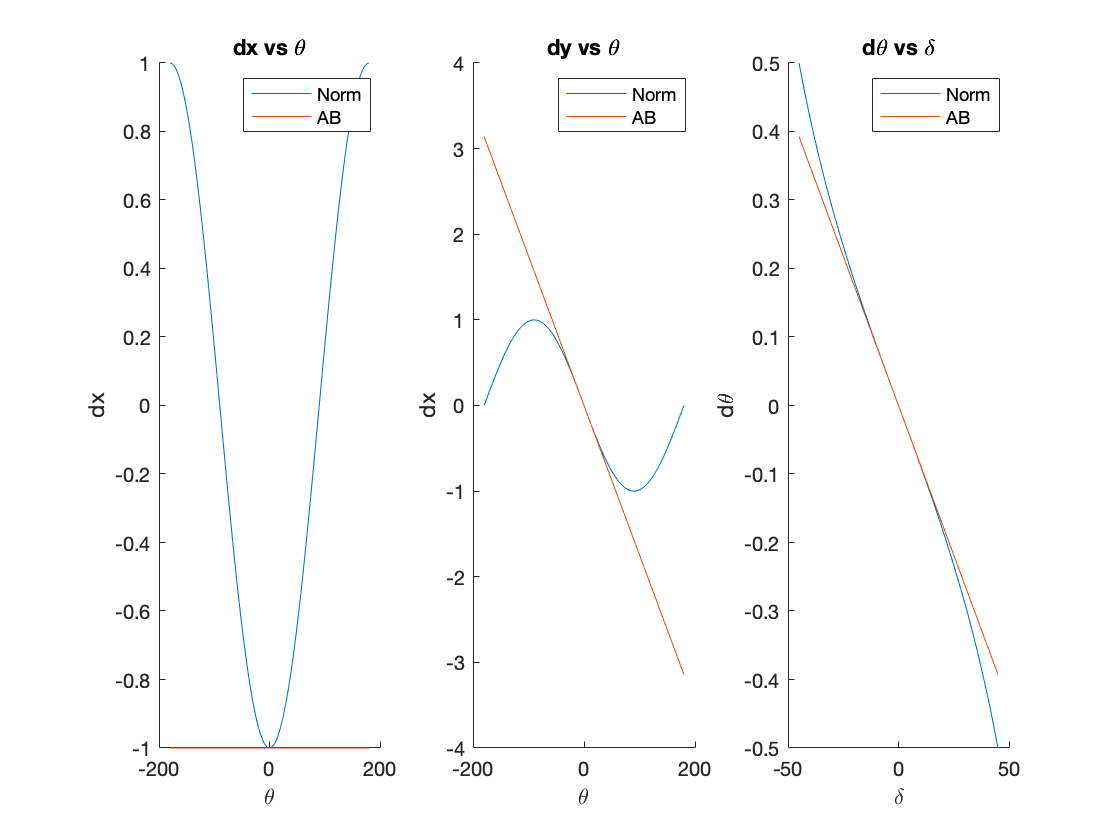


subplot(1,3,3), hold on
plot(rad2deg(deltas),dtheta1)
plot(rad2deg(deltas),dtheta2)
% plot(rad2deg(deltas),dtheta3,'k')
title("d\theta vs \delta")
xlabel("\delta")
ylabel("d\theta")
legend("Norm","AB","AB linearised")

#### Helper functions

function M = applySmallAngleApproximations(M)
    M = mapSymType(M,'sin',@(x)children(x));
    M = mapSymType(M,'cos',@(x)1);
    M = mapSymType(M,'tan',@(x)children(x));
end
